**Step #1 Load Data**

imageFolder = '/MATLAB Drive/IMSS2TASK5/mask'

imageFolder = '/mask/mask off'

imds = imageDatastore(imageFolder,'LabelSource','foldernames','IncludeSubfolders',true);

Error using imageDatastore
Cannot find files or folders matching: '/mask/mask off'.

**Step #2 Show Loaded Data**

tbl = countEachLabel(imds);

**Step #3 Process and Verify Data**

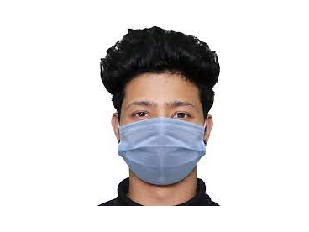

%Split data
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7); 

%Show a random image
sampleImage = readimage(imdsTrain,randi(numel(imdsTrain.Files))); 
imshow(sampleImage);

**Step #4 Import Network and Resize Data**

%import googlenet
net = googlenet;

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain); augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

% pull a test sample
test_sample_table = augimdsTrain.readByIndex(1); test_sample = test_sample_table.input{1};

% use GoogLeNet to classify image
label = classify(net,test_sample)

label = categorical
     wig 


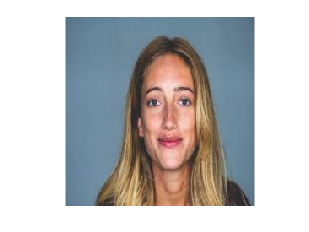

imshow(test_sample);

**Step #5 Transfer Learning**

lgraph = layerGraph(net);
numClasses = numel(categories(imdsTrain.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ... 
    'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);

lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer); 
newClassLayer = classificationLayer('Name','new_classoutput'); 
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Plots','training-progress');

newNet = trainNetwork(augimdsTrain,lgraph,options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |       60.00% |       0.7426 |          0.0003 |
|       6 |          24 |       00:00:24 |      100.00% |       0.0008 |          0.0003 |
|========================================================================================|
Training finished: Max epochs completed.


** Step #6 Classify on New Data**

[YPred,probs] = classify(newNet,augimdsValidation); 
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 1

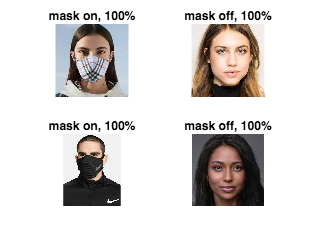

% And view individual images
idx = randperm(numel(imdsValidation.Files),4); 
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end